f = 44100;
T = 1/f;

wc = 7000;

Gs = tf([wc^2],[1 2*wc wc^2]);

Gz = c2d(Gs, T)

Gz =
 
   0.01134 z + 0.0102
  ---------------------
  z^2 - 1.706 z + 0.728
 
Sample time: 2.2676e-05 seconds
Discrete-time transfer function.
Model Properties


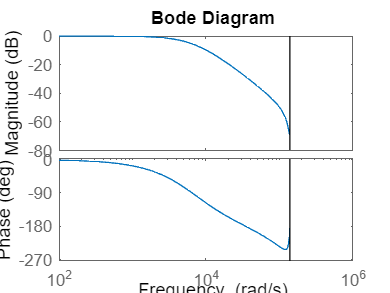


bode(Gz);